clear
close all

syms a b c m n p real positive
syms t real
syms x(t) y(t)


ode1 = diff(x,t) == a*x -b*y

$$ode1(t) = \frac{\partial }{\partial t}x\left(t\right)=a\,x\left(t\right)-b\,y\left(t\right)$$

ode2 = diff(y,t) == m*y - n*x

$$ode2(t) = \frac{\partial }{\partial t}y\left(t\right)=m\,y\left(t\right)-n\,x\left(t\right)$$

odes = [ode1; ode2]

$$odes(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)=a\,x\left(t\right)-b\,y\left(t\right)\\ \frac{\partial }{\partial t}y\left(t\right)=m\,y\left(t\right)-n\,x\left(t\right) \end{array}\right)$$

x0 = 1;
y0 = 1;
cond1 = x(0) == x0

$$cond1 = x\left(0\right)=1$$

cond2 = y(0) == y0

$$cond2 = y\left(0\right)=1$$

conds = [cond1; cond2]

$$conds = \left(\begin{array}{c} x\left(0\right)=1\\ y\left(0\right)=1 \end{array}\right)$$

pretty(odes)

/  d                         \
| -- x(t) == a x(t) - b y(t) |
| dt                         |
|                            |
|  d                         |
| -- y(t) == m y(t) - n x(t) |
\ dt                         /



pretty(conds)

/ x(0) == 1 \
|           |
\ y(0) == 1 /



s = dsolve(odes, conds)

s = 包含以下字段的 struct :
    y: [1×1 sym]
    x: [1×1 sym]



xsol(t) = s.x

$$xsol(t) = \begin{array}{l} \frac{{\mathrm{e}}^{\frac{t\,\left(a+m+\sigma_{1}\right)}{2}}\,\left(\frac{\frac{a}{2}+\frac{m}{2}+\frac{\sigma_{1}}{2}}{n}-\frac{m}{n}\right)\,\left(a-m+2\,n-\sigma_{1}\right)}{2\,\sigma_{1}}-\frac{{\mathrm{e}}^{\frac{t\,\left(a+m-\sigma_{1}\right)}{2}}\,\left(\frac{\frac{a}{2}+\frac{m}{2}-\frac{\sigma_{1}}{2}}{n}-\frac{m}{n}\right)\,\left(a-m+2\,n+\sigma_{1}\right)}{2\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{a^{2}-2\,a\,m+m^{2}+4\,b\,n} \end{array}$$

ysol(t) = s.y

$$ysol(t) = \begin{array}{l} \frac{{\mathrm{e}}^{\frac{t\,\left(a+m-\sigma_{1}\right)}{2}}\,\left(a-m+2\,n+\sigma_{1}\right)}{2\,\sigma_{1}}-\frac{{\mathrm{e}}^{\frac{t\,\left(a+m+\sigma_{1}\right)}{2}}\,\left(a-m+2\,n-\sigma_{1}\right)}{2\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{a^{2}-2\,a\,m+m^{2}+4\,b\,n} \end{array}$$

a0 = 2

a0 = 2

b0 = 1

b0 = 1

c0 = 1

c0 = 1

m0 = 3

m0 = 3

n0 = 5

n0 = 5

p0 = 1

p0 = 1


xsol1 = subs(xsol, [a b c m n p],[a0 b0 c0 m0 n0 p0])

$$xsol1(t) = \frac{\sqrt{21}\,{\mathrm{e}}^{-\frac{t\,\left(\sqrt{21}-5\right)}{2}}\,\left(\frac{\sqrt{21}}{10}+\frac{1}{10}\right)\,\left(\sqrt{21}+9\right)}{42}-\frac{\sqrt{21}\,{\mathrm{e}}^{\frac{t\,\left(\sqrt{21}+5\right)}{2}}\,\left(\frac{\sqrt{21}}{10}-\frac{1}{10}\right)\,\left(\sqrt{21}-9\right)}{42}$$

ysol1 = subs(ysol, [a b c m n p], [a0 b0 c0 m0 n0 p0])

$$ysol1(t) = \frac{\sqrt{21}\,{\mathrm{e}}^{-\frac{t\,\left(\sqrt{21}-5\right)}{2}}\,\left(\sqrt{21}+9\right)}{42}+\frac{\sqrt{21}\,{\mathrm{e}}^{\frac{t\,\left(\sqrt{21}+5\right)}{2}}\,\left(\sqrt{21}-9\right)}{42}$$


T = 5

T = 5

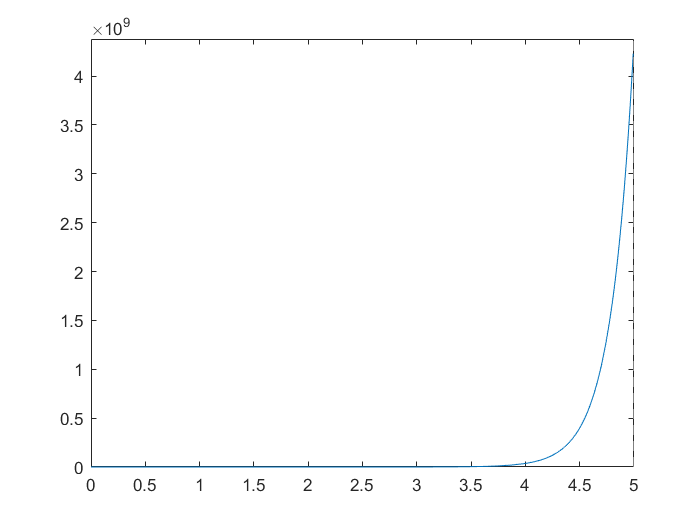

fplot(xsol1, [0 T])

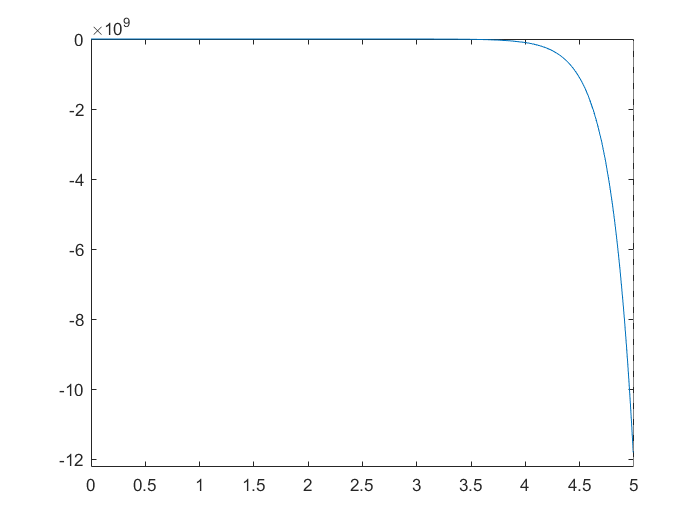

fplot(ysol1, [0 T])